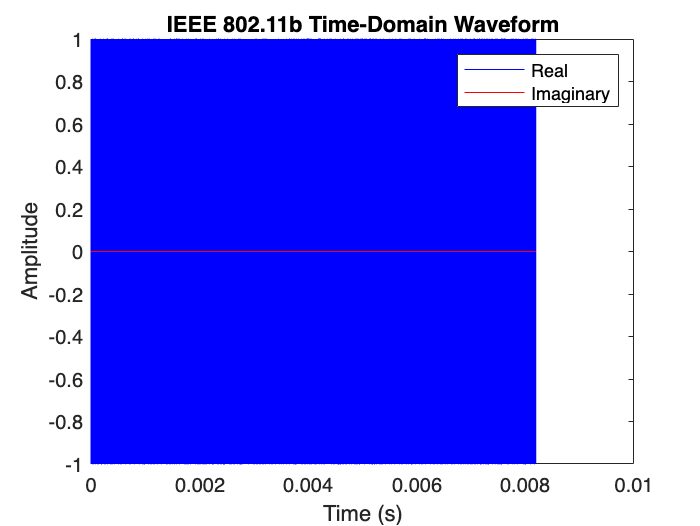

load('test1.mat');

% Extract relevant information
waveform = waveStruct.waveform;
Fs = waveStruct.Fs;

% Plot the time-domain waveform
time = (0:length(waveform)-1) / Fs;
figure;
plot(time, real(waveform), 'b', time, imag(waveform), 'r');
title('IEEE 802.11b Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Real', 'Imaginary');

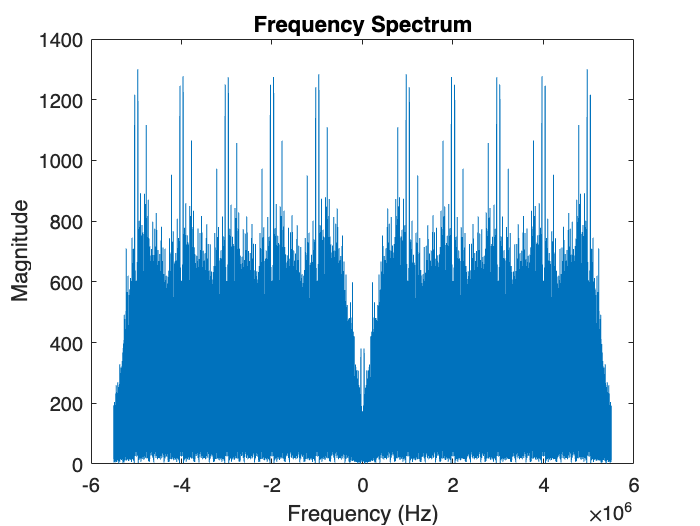


% Compute and plot the frequency-domain spectrum
spectrum = fftshift(fft(waveform));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Extract relevant information
waveform = waveStruct.waveform;
Fs = waveStruct.Fs;
exist('wlan80211Decoder', 'file')

ans = 0


demodulatedSymbols = pskdemod(waveStruct);

Error using pskdemod
Not enough input arguments.